clear;
close all;
clc;
K = 500;
A = 2;
omega1 = pi / 3;
omega2 = pi;
phi = pi;
m = (1:100).';
y = A * exp(1i * omega1 * m + phi) + A * exp(1i * omega2 * m + phi);
Y = fft(y, K);
AY = abs(Y);
% x=D1IAA_1text(y,K);
% x=D1IAA(y,K);
x = D1IAA_1(y, K);

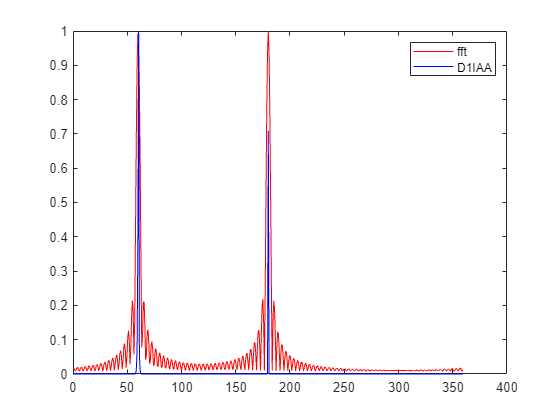

Ax = abs(x);
b = 0:K - 1;
figure;
plot(b * 360 / K, AY / max(AY), 'r'), hold on;
plot(b * 360 / K, Ax / max(Ax), 'b'), hold on;
legend('fft', 'D1IAA');